##  E_E 521 Analysis of Power Systems

### Power Flow Project

### Sajjad Uddin Mahmud | WSU ID: 011789534

### Initializing MATLAB

close all;
clear all;
clc;

### Reading The IEEE Test System Data

In this project, we study IEEE 14 Bus test system.

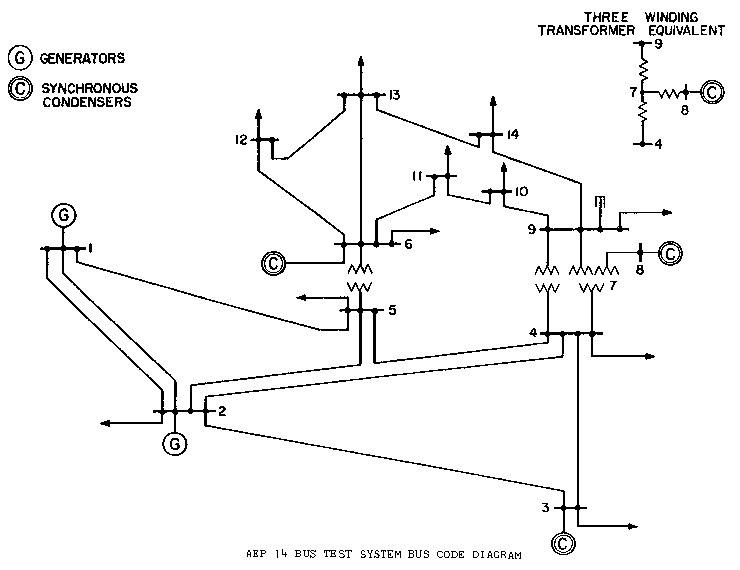

Fig. 01: IEEE 14 Bus Power System

At first, we read the data from the IEEE 14 Bus test system from a pre-formatted excel file which has been created from the [ieee14cdf.txt](http://labs.ece.uw.edu/pstca/pf14/pg_tca14bus.htm).

% Setting Up The Path
Workspace = "Lab"

Workspace = "Lab"


if Workspace == "Lab"
    addpath('D:\One_Drive_Sajjad\OneDrive - Washington State University (email.wsu.edu)\Documents\Sajjad Uddin Mahmud\1. Courses\2. Fall 2022\EE 521 Analysis of Power System\Assignment\EE 521 Power Flow Project 01');
elseif Workspace == "Home"
    addpath('E:\EE 521\PowerFlow');
end


%% Reading From Bus Data

% Bus Number
Bus_Number_Data = xlsread('IEEE14_Formatted.xlsx','A3:A16');
Total_Bus = max(Bus_Number_Data);

% Bus Type
Bus_Type_Data = xlsread('IEEE14_Formatted.xlsx','G3:G16');
PQ_Bus_Type = 0;
PV_Bus_Type = 2;
Slack_Bus_Type = 3;
Bus = Bus_Number_Data(find(Bus_Type_Data ~= Slack_Bus_Type));  % Bus Data Except Slcak Bus
Bus_Type = Bus_Type_Data(Bus);

% Bus Information
Base_MVA_Data = 100;
P_Load_Data = xlsread('IEEE14_Formatted.xlsx','J3:J16')/Base_MVA_Data; % Load MW pu
Q_Load_Data = xlsread('IEEE14_Formatted.xlsx','K3:K16')/Base_MVA_Data; % Load MVAR pu
P_Gen_Data = xlsread('IEEE14_Formatted.xlsx','L3:L16')/Base_MVA_Data; % Generator MW pu
Q_Gen_Data = xlsread('IEEE14_Formatted.xlsx','M3:M16')/Base_MVA_Data; % Generator MVAR pu
V_Desired = xlsread('IEEE14_Formatted.xlsx','O3:O16'); % Desired Voltage

% Bus Shunt Conductance and Shunt Susceptance
G_Shunt_Bus_Data = xlsread('IEEE14_Formatted.xlsx','R3:R16');
B_Shunt_Bus_Data = xlsread('IEEE14_Formatted.xlsx','S3:S16');


% Reading From Branch Data

% Branch Number
From_Bus_Data = xlsread('IEEE14_Formatted.xlsx','A19:A38');
To_Bus_Data = xlsread('IEEE14_Formatted.xlsx','B19:B38');

% Branch Resistance Per Unit
R_Branch_Data = xlsread('IEEE14_Formatted.xlsx','G19:G38');

% Branch Reactance Per Unit
X_Branch_Data = xlsread('IEEE14_Formatted.xlsx','H19:H38');

% Line Charging B Per Unit
B_Branch_Data = xlsread('IEEE14_Formatted.xlsx','I19:I38');

% Transformer Final Turns Ratio
XFR_TurnRatio_Data = xlsread('IEEE14_Formatted.xlsx','O19:O38');

### Creating Y Bus

At first we create a empty matrix for Y bus of a dimension based on the total bus number of the test system.

% Initializing Y Bus
Y_Bus = zeros(Total_Bus);

We calculate impedance and admittance of each branch.

Branch impedance between bus a and b: $$z_{ab} = r_{ab} + jx_{ab}$$ and branch admittance between bus a and b:  $$y_{ab}=\frac{1}{z_{ab}} = \frac{1}_{ r_{ab} + jx_{ab}}$$

Z_Branch = zeros(length(From_Bus_Data),1);
Y_Branch = zeros(length(From_Bus_Data),1);

% Loop: Calculating Branch Impedance and Admittance
for i = 1:length(From_Bus_Data)
    Z_Branch(i) = R_Branch_Data(i) + 1j*X_Branch_Data(i); % Per Unit Impedance
    Y_Branch(i) = 1/(Z_Branch(i)); % Per Unit Admittance
end

We also calculate the bus own shunt admittance.

% Calculating Bus Shunt Admittance
Y_Shunt_Bus = G_Shunt_Bus_Data + 1j*B_Shunt_Bus_Data;

Next, we calculate the off-diagonal entries of the Y bus matrix.

If we do not consider taps then:

Diagonal entries: $$Y_{aa}=\sum_{k=1}^N (y_{ak} + j \frac{B_{ak}}{2 })+jB_{a}=\sum_{k=1}^N( \frac{1}{r_{ak}+jx_{ak}} + j \frac{B_{ak}}{2 })+jB_{a}$$

Off-Diagonal entries: $$Y_{ab}=Y_{ba}=- (\sum y_{ab})$$

If we consider taps then:

Diagonal entries: $$Y_{aa}=\sum_{k=1}^N [((\frac{1}{tap_{(k)}})^2\times y_{ak})+ j \frac{B_{ak}}{2 }]+jB_{a}=\sum_{k=1}^N[(( \frac{1}{tap_{(k)}})^2\times (\frac{1}{r_{ak}+jx_{ak}} ))+ j \frac{B_{ak}}{2 }]+jB_{a}$$

Off-Diagonal entries: $$Y_{ab}=Y_{ba}= - (\sum \frac{1}{tap_{(ab)}}\times y_{ab})$$

% Transformer Tap Consideration
Tap_Consideration = "Yes";


if (Tap_Consideration == "No")
    for i = 1:length(XFR_TurnRatio_Data)
        XFR_TurnRatio_Data(i) = 0; % If we do not consider tap, we set all the turn ratio of transformer as 0
    end
end

% Loop: Calculating Diagonal and Off-Diagonal Entries of The Y Bus Matrix
for i = 1:length(Y_Branch)
    a = From_Bus_Data(i);
    b = To_Bus_Data(i);
    Tap = XFR_TurnRatio_Data(i); 

    if (Tap == 0)
        Y_Bus(a,a) = Y_Bus(a,a) + Y_Branch(i) + 1j*(B_Branch_Data(i)/2);
        Y_Bus(a,b) = Y_Bus(a,b) - Y_Branch(i);
        Y_Bus(b,a) = Y_Bus(a,b);

    else
        t = 1/(XFR_TurnRatio_Data(i));
        Y_Bus(a,a) = Y_Bus(a,a) + ((t^2) * (Y_Branch(i))) + 1j*(B_Branch_Data(i)/2);
        Y_Bus(a,b) = Y_Bus(a,b) - (t * Y_Branch(i));
        Y_Bus(b,a) = Y_Bus(a,b);
    end
    Y_Bus(b,b) = Y_Bus(b,b) + Y_Branch(i) + 1j*(B_Branch_Data(i)/2);
end


% Loop: Adding Bus Shunt Admittance
for i = 1:length(Total_Bus)
    Y_Bus(i,i) = Y_Bus(i,i) + Y_Shunt_Bus(i); 
end


% Converting Y Bus Data into Polar Form
[Y_Bus_Theta, Y_Bus_Rho] = cart2pol(real(Y_Bus), imag(Y_Bus)); % The Theta are in radian

Rho = abs(Y_Bus);
Theta = angle(Y_Bus);
B = imag(Y_Bus);
G = real(Y_Bus);

### Power Flow: Jacobian Matrix

The real and reactive powers of each bus are calculated from the initial voltage magnitude and angle. If real power $$P_i$$ and reactive power $$Q_i$$ enters the network from bus $$i$$, then the power flow equations are:


$$$P_i = \sum_{n=1}^N |Y_{in} V_i V_n| cos( \theta_{in}+\delta_n-\delta_i)$$



$$$Q_i = - \sum_{n=1}^N |Y_{in} V_i V_n| sin( \theta_{in}+\delta_n-\delta_i)$$


% Schedule Real and Reactive Power
P_Scheduled = transpose(P_Gen_Data - P_Load_Data);
Q_Scheduled = transpose(Q_Gen_Data - Q_Load_Data);


% Initial Voltage Magnitude and Angle
V = ones(1,length(Bus_Number_Data));
V(1,find(V_Desired)) = V_Desired(find(V_Desired),1);
Delta = zeros(1,length(Bus_Number_Data));


% Loop: Calculating Real Power
P_Calculated = zeros(1, Total_Bus);

for i = 1:Total_Bus
    for j = 1:Total_Bus
        P_Calculated(i) = P_Calculated(i) + (abs(abs(Y_Bus(i,j)) * V(i) * V(j))) * (cos(angle(Y_Bus(i,j)) + Delta(j) - Delta(i)));
    end
end


% Loop: Calculating Reactive Power
Q_Calculated = zeros(1, Total_Bus);

for i = 1:Total_Bus
    for j = 1:Total_Bus
        Q_Calculated(i) = Q_Calculated(i) + (abs(abs(Y_Bus(i,j)) * V(i) * V(j))) * (sin(angle(Y_Bus(i,j)) + Delta(j) - Delta(i)));
    end
    Q_Calculated(i) = - Q_Calculated(i);
end


% Calculating Mismatch
Delta_P = P_Scheduled - P_Calculated;
Delta_Q = Q_Scheduled - Q_Calculated;


% Initializating Jacobian Matrix
J11 = zeros(length(Bus));
J12 = zeros(length(Bus));
J21 = zeros(length(Bus));
J22 = zeros(length(Bus));


% Loop: Forming Jacobian
for i = 1:length(Bus)
    for j = 1:length(Bus)
        if (i == j) % Diagonals Entries
            J11(i,j) = - Q_Calculated(Bus(i)) - ((V(Bus(i)))^2) * B(Bus(i),Bus(i));
            J21(i,j) = P_Calculated(Bus(i)) - ((V(Bus(i)))^2) * G(Bus(i),Bus(i));
            J12(i,j) = P_Calculated(Bus(i)) + ((V(Bus(i)))^2) * G(Bus(i),Bus(i));
            J22(i,j) = Q_Calculated(Bus(i)) - ((V(Bus(i)))^2) * B(Bus(i),Bus(i));
        else % Off-Diagonal Entries
            J11(i,j) = - abs(V(Bus(i)) * V(Bus(j)) * Rho(Bus(i),Bus(j))) * sin(Theta(Bus(i),Bus(j)) + Delta(Bus(j)) - Delta(Bus(i)));
            J21(i,j) = - abs(V(Bus(i)) * V(Bus(j)) * Rho(Bus(i),Bus(j))) * cos(Theta(Bus(i),Bus(j)) + Delta(Bus(j)) - Delta(Bus(i)));
            J12(i,j) = - J21(i,j);
            J22(i,j) = J11(i,j);
        end
    end
end


% Removing Rows and Columns from Jacobian for PV Bus
PV = find(Bus_Type == PV_Bus_Type);
J12(:,PV) = [];
J21(PV,:) = [];
J22(:,PV) = [];
J22(PV,:) = [];


% Jacobian Matrix
J = [J11 J12; J21 J22];







